## Basic Spectral Analysis

[https://se.mathworks.com/help/matlab/math/basic-spectral-analysis.html](https://se.mathworks.com/help/matlab/math/basic-spectral-analysis.html)

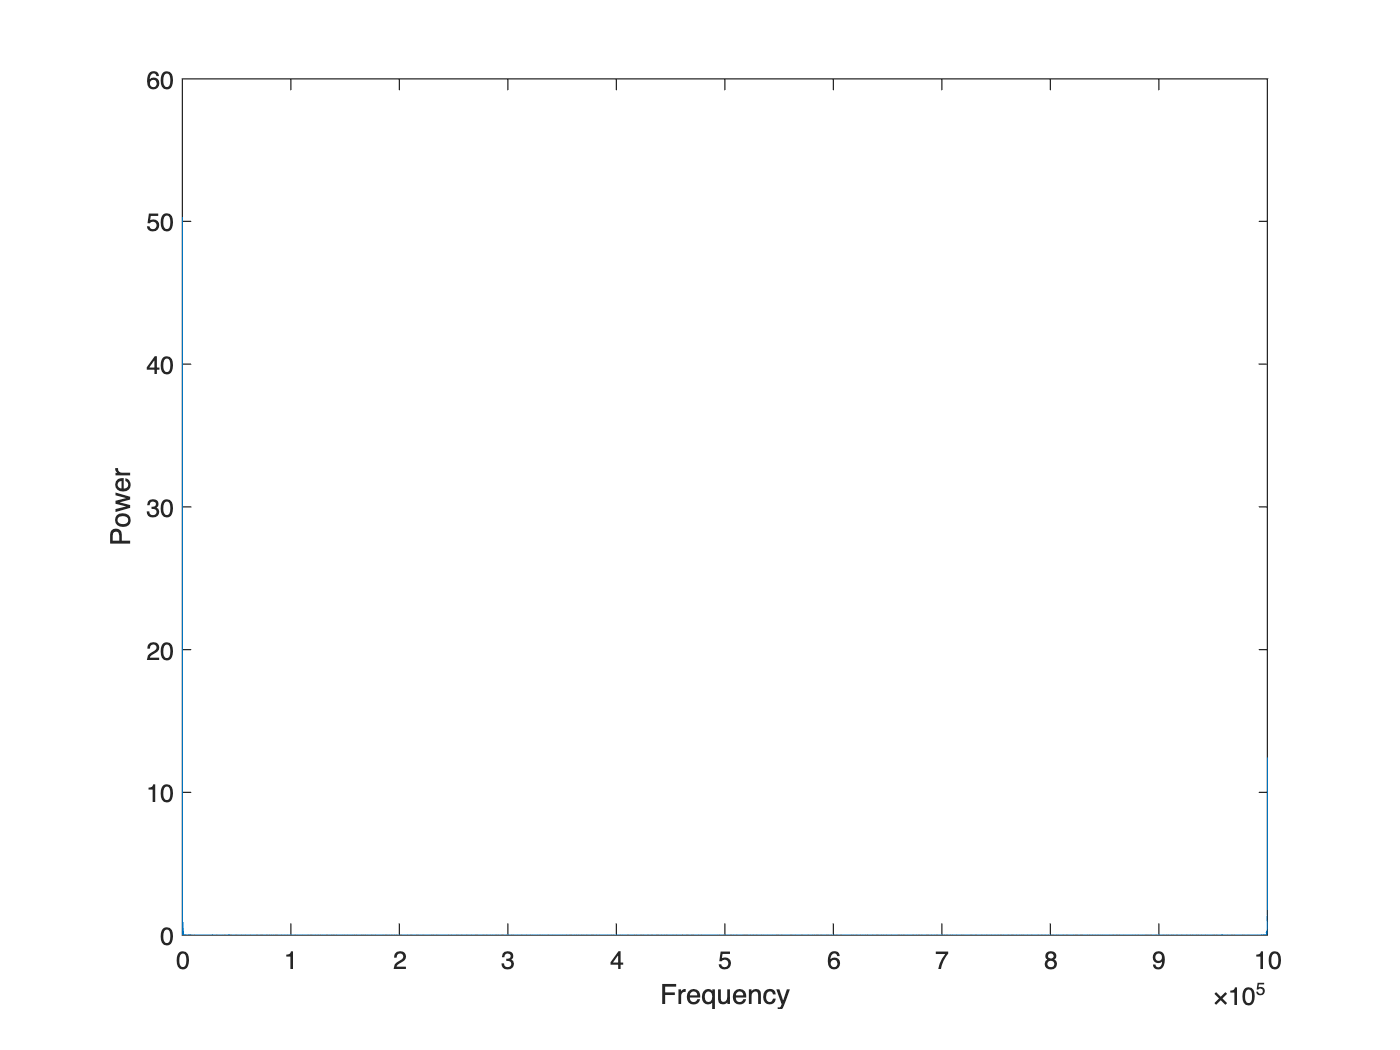

% Import the file
load('E2038.mat');
n = length(p);
time = (0:0.000001:n/1000000-0.000001)';
x = pz(:,3);
y = fft(x);
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y).^2/n;    % power of the DFT

plot(f,power)
xlabel('Frequency')
ylabel('Power')

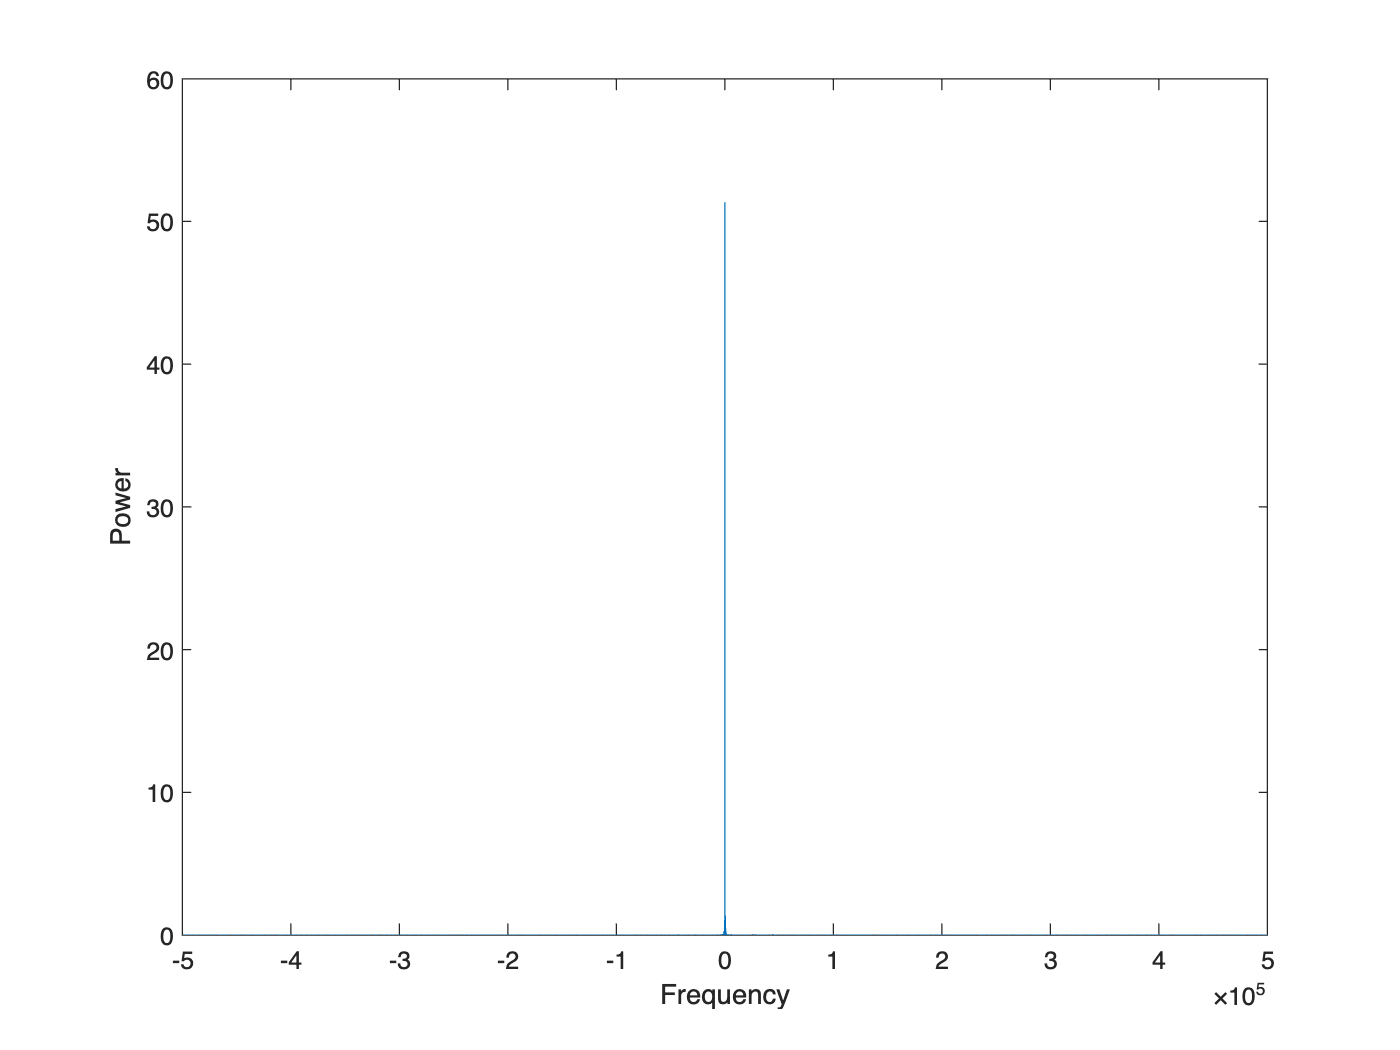

y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n;    % 0-centered power

plot(f0,power0)
xlabel('Frequency')
ylabel('Power')